## 加载数据集

XTrain = datastes; YTrain = labeltes;
clear datastra datasval labeltra labelval lentra lenval lentes meantra meanval stdtra stdval labelclasses;

## 定义网络架构

% Generator Network
numLatentInputs = 128;
embeddingDimension = 50;
numFilters = 64;
filterSize = 5;
projectionSize = [5, 1, 1024];
numInputChannels = numaccelerator;

layersGenerator = [
    imageInputLayer([1 1 numLatentInputs],'Normalization','none','Name','in')
    projectAndReshapeLayer(projectionSize,numLatentInputs,'proj');
    concatenationLayer(3,2,'Name','cat');

    transposedConv2dLayer([filterSize, 1],8*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],4*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],2*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],1*numFilters,Stride=[3,1],Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer([filterSize, 1],numInputChannels,Stride=[2,1],Cropping="same")];

lgraphGenerator = layerGraph(layersGenerator);

layers = [
    imageInputLayer([1 1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(projectionSize(1:2),embeddingDimension,numClasses,'emb')];

lgraphGenerator = addLayers(lgraphGenerator,layers);
lgraphGenerator = connectLayers(lgraphGenerator,'emb','cat/in2');
dlnetGenerator = dlnetwork(lgraphGenerator);

% Discriminator Network

scale = 0.2;
inputSize = [lenaccelw lenaccelh numaccelerator];

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')
    concatenationLayer(3,2,'Name','cat')

    convolution2dLayer([filterSize, 1],2*numFilters,Stride=[3,1],Padding="same")
    leakyReluLayer(scale)
    convolution2dLayer([filterSize, 1],4*numFilters,Stride=[3,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer([filterSize, 1],8*numFilters,Stride=[3,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer([filterSize, 1],4*numFilters,Stride=[3,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer([filterSize, 1],4*numFilters,Stride=[4,1],Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer([filterSize, 1],numInputChannels,Stride=[3,1],Padding="same")];

lgraphDiscriminator = layerGraph(layersDiscriminator);

layers = [
    imageInputLayer([1 1],'Name','labels','Normalization','none')
    embedAndReshapeLayer(inputSize,embeddingDimension,numClasses,'emb')];

lgraphDiscriminator = addLayers(lgraphDiscriminator,layers);
lgraphDiscriminator = connectLayers(lgraphDiscriminator,'emb','cat/in2');
dlnetDiscriminator = dlnetwork(lgraphDiscriminator);

## Specify Training Options

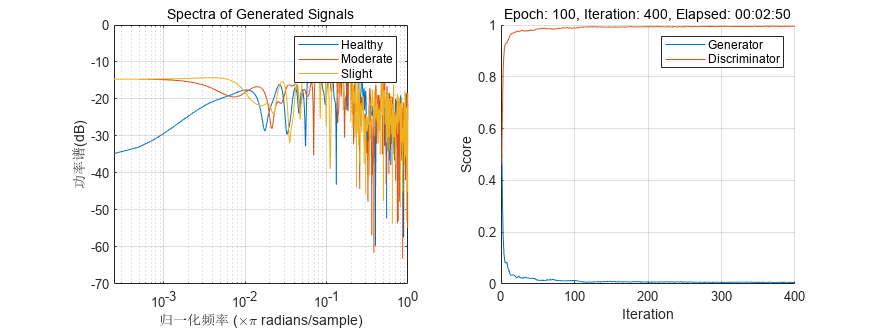

params.numLatentInputs = numLatentInputs;
params.numClasses = numClasses;
params.sizeData = [inputSize length(YTrain)];
params.numEpochs = 100;
params.miniBatchSize = 256;
params.executionEnvironment = "gpu";
% Specify the options for Adam optimizer
params.learnRate = 0.0002;
params.gradientDecayFactor = 0.5;
params.squaredGradientDecayFactor = 0.999;
% 开始训练
[dlnetGenerator,dlnetDiscriminator] = trainGAN(dlnetGenerator,dlnetDiscriminator,XTrain,YTrain,params);

## 合成信号

rng default

numTests = 1200;
ZNew = randn(1,1,numLatentInputs,numTests,'single');
dlZNew = gpuArray(dlarray(ZNew,'SSCB'));

TNew = ones(1,1,1,numTests,'single');
TNew(1,1,1,numTests/3+1:2*numTests/3) = single(2);
TNew(1,1,1,2*numTests/3+1:end) = single(3);
dlTNew = gpuArray(dlarray(TNew,'SSCB'));
dlXGeneratedNew = predict(dlnetGenerator,dlZNew,dlTNew)*stdtes+meantes;
dlXGeneratedNew = squeeze(extractdata(gather(dlXGeneratedNew)));

## Principal Component Analysis（PCA）

% 数据处理
idxGenerated = 1:numTests; idxReal = numTests+1:numTests+size(XTrain,2);

函数 'extractdata' 的输入或输出的数目或类型不正确。

x = [dlXGeneratedNew single(XTrain)]; % 数据长度*（生成样本数+原有样本数）
features = zeros(size(x,2),14,'like',x); % 提取特征（样本数*14个特征）
for ii = 1:size(x,2)
    features(ii,:) = extractFeatures(x(:,ii));
end
% PCA via svd
featuresReal = features(idxReal,:);
mu = mean(featuresReal,1);
[~,S,W] = svd(featuresReal-mu);
Y = (features-mu)*W;
% 判断前三个量的占比
S = diag(S);
asum = sum(S(1:3))/sum(S);
L = [squeeze(TNew)+2; YTrain]; % 标签总长度
idxHealthyR = L==1;
idxModerateR = L==2;
idxSlightR = L==3;

idxHealthyG = L==4;
idxModerateG = L==5;
idxSlightG = L==6;

pp = Y(:,1:3);

figure
scatter3(pp(idxHealthyR,1),pp(idxHealthyR,2),pp(idxHealthyR,3),'o')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
zlabel('3rd Principal Component')
hold on
scatter3(pp(idxModerateR,1),pp(idxModerateR,2),pp(idxModerateR,3),'d')
scatter3(pp(idxSlightR,1),pp(idxSlightR,2),pp(idxSlightR,3),'s')
scatter3(pp(idxHealthyG,1),pp(idxHealthyG,2),pp(idxHealthyG,3),'+')
scatter3(pp(idxModerateG,1),pp(idxModerateG,2),pp(idxModerateG,3),'d')
scatter3(pp(idxSlightG,1),pp(idxSlightG,2),pp(idxSlightG,3),'d')
view(-10,20)
legend('Real Healthy','Real Moderate','Real Slight',...
    'Generated Healthy','Generated Moderate','Generated Slight', ...
    'Location','Best')
hold off
view(2)